# Starter script for the Swiss Ma    thWorks AI Hackathon - 2023

Hi and welcome to the Swiss MathWorks AI Hackathon 2023! It is exciting to see you here, and by the time you go through this exercise, hopefully your knowledge and expertise with AI models for image classification moves on to a different higher plane ;-) 

The challenge we are attempting to address is the well-known "rock, paper, scissors" or "piedra Papel tijeras" if you speak Spanish, using a computer program to detect if an image of the hand is one of the three categories. For us humans, it is likely rather easy to make the distinction, unless one does something like this:

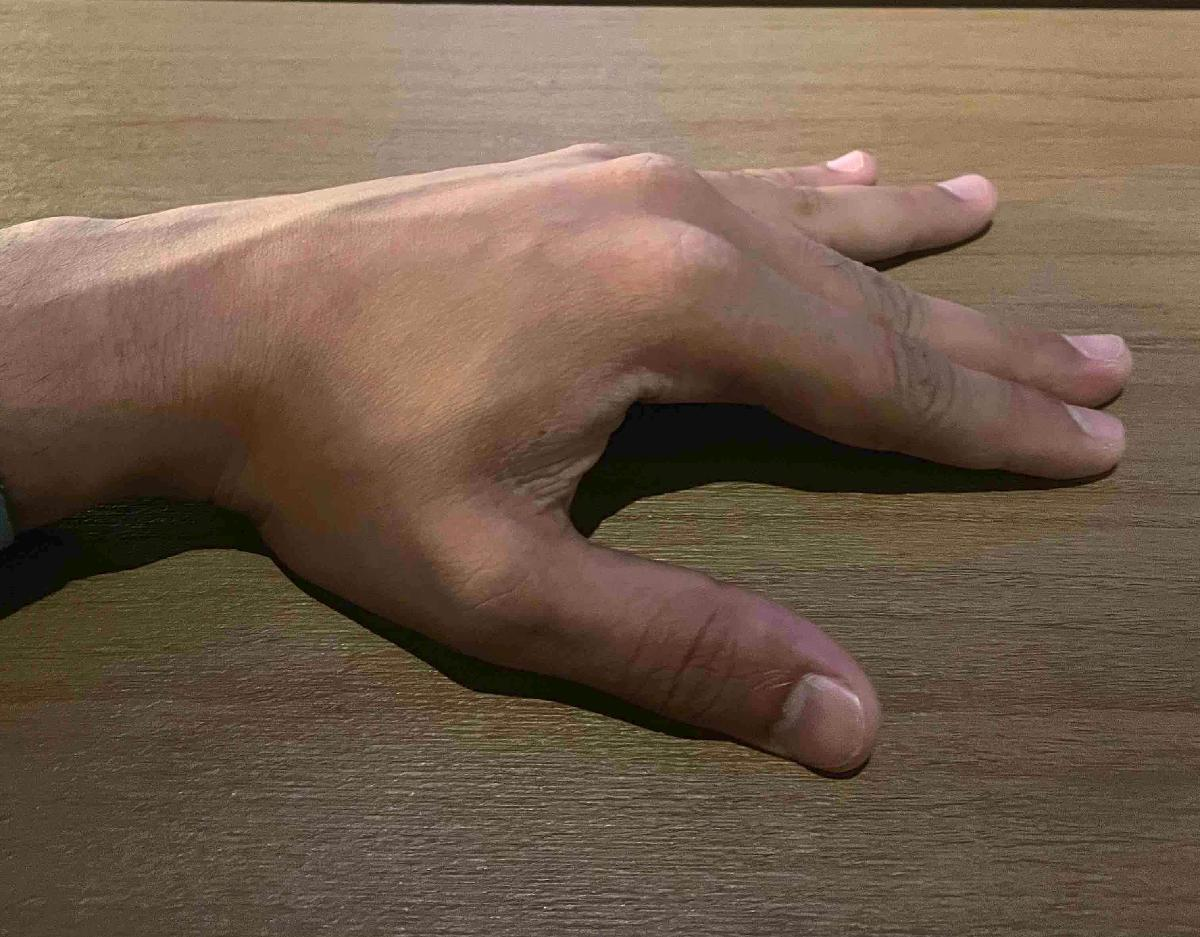

(is this paper or scissors, or something in between?)

In the next few sections of this document, we will go through a step-by-step process of building a deep neural network to take as input images like this, and return at the output what the sign is: one of either rock, paper, or scissors. 

Run the following lines to start with a "clean" workspace so nothing unexpected happens! 

clearvars; close all; 
imtool close all;

## Starting out: building on "pre-trained" models

What's exciting with AI is that you don't need to start from scratch all the time. There are some reasonably "intelligent" starting points called "pre-trained models", which one could use to get a head-start while creating something useful for ones' own projects. For the case of image classification, there are a family of such models (think of a model as a black box function, that takes in images and spits out text categories) that can help. In this situation, we use a well-known model called ResNet-18, which stands for residual network, with 18 "layers". What a layer is, and what the difference between a model and a network is, will be elaborated soon - keep reading! 

To create a ResNet-18 model in MATLAB, all you really need is the resnet18 support package. If the Deep Learning Toolbox Model *for ResNet-18 Network* support package is not installed, then the function provides a link to the required support package in the Add-On Explorer. To install the support package, click the link, and then click **Install**.

% net holds the 'network' or 'model' we use to perform classification.
net = resnet50();

% Store the size of the image this model takes in as imSize
imSize = net.Layers(1).InputSize;

## Loading data: and splitting into training and testing

What separates AI from "regular" computer programs is that they need some data to learn from. This data is generally in the same form as the input it receives while we want to use it in usual practice (for example, an image of a hand to classify into rock, paper or scissors). What is necessary also in the specific case of "supervised learning" is that the data needs to have associated labels - so that the AI can learn by example and try to generalize its' understanding of the data to new scenarios it sees later on. 

Fortunately, we also have these days many data sets that are already labeled, and we are going to use one such data set for this challenge. You can find this data set in the folder /SwissAIHackathon/TrainingData.

The following lines of code open a file browser to select the data source - and then also automatically splits the large set of images into training, test, and validation. 

trainingFolderPath = "./TrainingData7"; %uigetdir(".", "Choose the downloaded trainingImages folder");
imds = imageDatastore(trainingFolderPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% To view the images in MATLAB - run the following commented line.
%imageBrowser(imds)

Now, we use `splitEachLabel` to create three datastores - train, test, and valid. These are used in various stages of building and testing the model we create. Broadly, the training set is used by the AI model to learn the patterns in the images so that it really attempts to become "intelligent". The test data is like the final exam in a course - they contain images previously unseen by the AI model, which we use to check and verify if the model has indeed learnt what we wanted it to. Finally the validation set is a small set of images which is used to track the learning progress of the model - so while training we know that it is indeed learning something useful, or, if it is losing track of the patterns (think of this as intermediate little tests in a course you are teaching to the AI model). 

[trainDS, testDS, validDS] = splitEachLabel(imds, 0.799, 0.001, 0.2);

We also run some additional processing steps on each of these datastores - to ensure the sizes match, and, to run any optional augmentation steps (for the training set only).

% Here's one way to resize all images in a datastore - by using
% augmentedImageDatastore. 
validDS = augmentedImageDatastore(imSize(1:2), validDS);

% Another method: use transform function (recommended API) to resize all images in
% the test datastore.
testDS = transform(testDS, @(x) imresize(x, imSize(1:2)));

% For the training set - use imageDataAugmenter - you could also do this
% with transform - try that out if you'd like!
augmenter = imageDataAugmenter('RandXReflection', true, ...
                               'RandXTranslation', [-50 50], 'RandRotation', [-180 180]);

trainingData = augmentedImageDatastore(imSize(1:2),trainDS,'DataAugmentation',augmenter);

% numCats holds the number of categories of labels - 3 in our case.
numCats = numel(categories(imds.Labels));

## On to training: setting up the model

The "pre-trained" model loaded into 'net' was trained on a really large data set called imagenet, which has 1000 categories of images, all the way from horses, fish, and trains. We are rather interested in a small set of 3 categories, rock, paper or scissors, which means we need to update the model to know that it only needs to distinguish between these three groups. The code below updates 'net' by modifying the last few layers such that we can set it up for a three-class classification problem.

This step could also be done using the **Deep Network Designer** - and that's left as an exercise for you to explore!

% Modifying the Pretrained network
if isa(net, 'SeriesNetwork')
    lgraph = layerGraph(net.Layers);
else
    lgraph = layerGraph(net);
end

lgraph = replaceLayer(lgraph, lgraph.Layers(end-2).Name, fullyConnectedLayer(numCats, 'Name', lgraph.Layers(end-2).Name));
lgraph = replaceLayer(lgraph, lgraph.Layers(end-1).Name, softmaxLayer('Name', lgraph.Layers(end-1).Name));
lgraph = replaceLayer(lgraph, lgraph.Layers(end).Name, classificationLayer('Name', lgraph.Layers(end).Name));

## Finally: training the model!

In this section, we setup the training. As with any complex system, there are many parameters you can setup to organize this. These knobs and switches you can modify before training are called hyperparameters. Each time some images "go through" the model for training, it is called an 'iteration'. Every time all the training images complete one pass through the model, it is called an 'epoch'. To limit the duration of training, we limit the run to 2 epochs, and setup validation checks (finding out how well the model is doing on images it has not seen so far) for every 5 iterations. 

Here's where you really get to tweak things and find out how it impacts the training scheme - what if the learning rate is too high, or too low? (change to 2 or 1e-8, and see how it impacts the training). Try changing the optimizer - we use 'rmsprop' here, but change it to 'adam' and check if the training is faster or slower, or doesn't converge? 

options = trainingOptions('rmsprop','MaxEpochs', 1, ...
    'InitialLearnRate', 0.0001, ...
    'Plots', 'training-progress', ...
    'ValidationData', validDS, ...
    'ValidationFrequency', 5, ...
    'CheckpointFrequency', 1, ...
    'CheckpointPath', 'checkpoints');
     %'OutputNetwork', 'best-validation-loss');

    

trainingData.MiniBatchSize = 256;

Finally, we train the classification network using `trainNetwork`.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:47 |       33.59% |       57.28% |       1.3410 |       1.0648 |      1.0000e-04 |
|       1 |           5 |       00:05:35 |       92.97% |       91.34% |       0.2325 |       0.2765 |      1.0000e-04 |
|       1 |          10 |       00:10:28 |       97.66% |       94.78% |       0.0770 |       0.1743 |      1.0000e-04 |
|       1 |          15 |       00:16:09 |       97.66% |       96.46% |       0.0736 |   

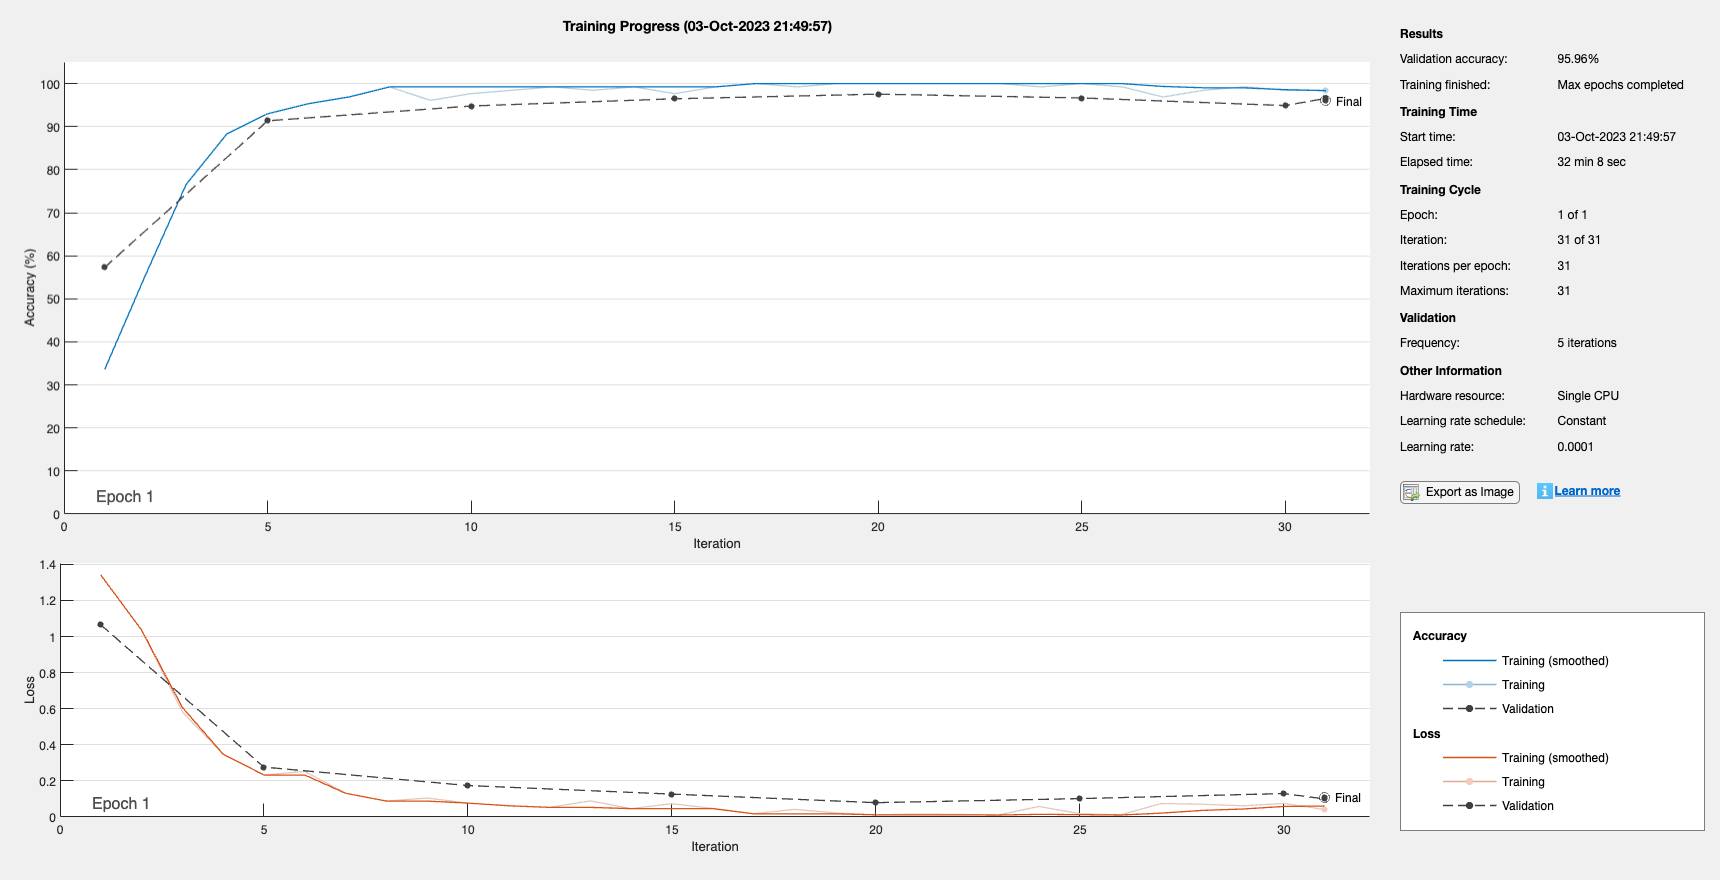

%Training
convnet = trainNetwork(trainingData, lgraph, options);

We save this trained network into a .mat file, with a time stamp so it is unique. 

latest_model_name = "rps-resnet50_D7_epochs1_1.mat";
save(latest_model_name,'convnet');

## Evaluation: how does the model do on the test set?

Remember we saved a portion of the data set in something called the 'test set'? We now are running the final exam for the model, where we evaluate how much it has learnt using these images: which it has never encountered earlier. The idea is to find out how well the model generalizes its' behavior to unseen data - likely what it will see also in "real life". The code in this section simply runs the classify function of the convnet model on the testDS datastore. 

[YTest, scores] = classify(convnet, testDS);

% Also measure accuracy - this is the percentage of matching labels in the
% test set. Note that we use the 'UnderlyingDatastore' part of the test
% dataset (because it is a 'transform' datastore to retrieve the labels.
TTest = testDS.UnderlyingDatastore.Labels;
accuracy = sum(YTest == TTest)/numel(YTest)

accuracy = 0.8333

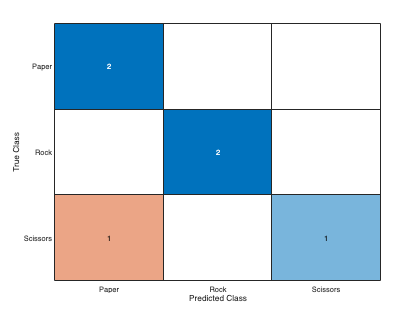

% Also plot the confusion chart.
confusionchart(TTest, YTest)

If this is sufficient evidence to prove general usability of this model, we can then run this model as an inference engine - by simply loading the .mat file containing the network, and running classify on a new image. In this demonstration, we use two random images from the original dataset, to show how this works. 

load(latest_model_name,"convnet");
mynet = convnet;
% Choose a random index from 1 to 200.
idx = randi(200, 1);
img = readimage(testDS.UnderlyingDatastore, idx);

Error using ImageDatastore
Expected index to be a scalar with value <= 6.

Error in matlab.io.datastore.ImageDatastore/readimage (line 28)
validateattributes(index, {'numeric'}, attribs, 'ImageDatastore', 'index');

img = imresize(img, [224 224]);

imR = imresize(img, mynet.Layers(1).InputSize(1:2));
label = classify(mynet, imR)

figure,
imshow(img)
title(fprintf("Predicted label: %s", label))

## Submitting your trained model to the leaderboard

Finally, if you are sufficiently satisfied with the performance of your trained model in the "final exam" of generalization, it is time to submit it to our secret test set (with more complicated images in different backgrounds and lighting conditions), to find out where you stand on the leaderboard! The below function will test your model against an online test set, and sends it to our leaderboard application. This process might take some minutes, and once done, your model will also be uploaded to an online repository, which might be used for the final evaluation of the competition.

Please supply your model and team name to the `submit` function as first and second argument, respectively. Please note that the model should be of the datatype "DAGNetwork".


team_name = "lever tf up";
submit(mynet, team_name)

Godspeed, and we wish you the best of luck in topping the charts! You have a whole week to stay up there, so remember the pole position can be overtaken by someone else! 

### Open the Leaderboard and compare with Competitors

You can open the leaderboard with the below command. Once the window opens you can synchronize it by clicking on the start button.

LeaderBoard

*Copyright 2023, The MathWorks, Inc.*